# Cart-Pole Problem

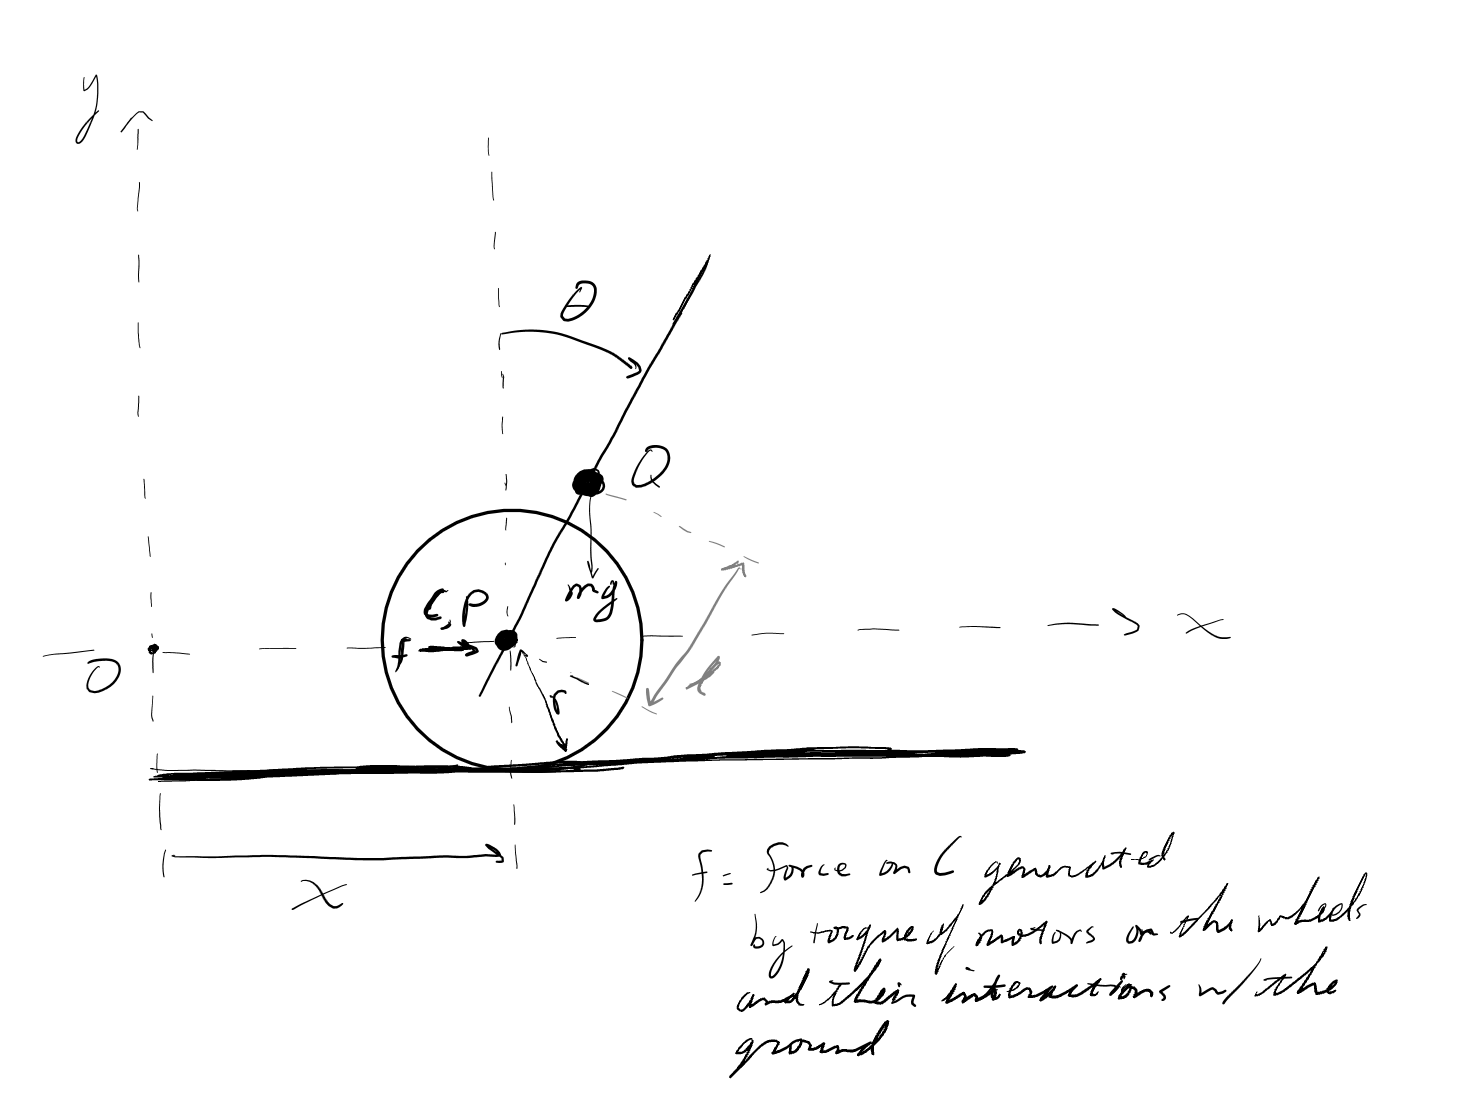

The equations of motion for the cart and the pole are as follows, where:

g = gravity = 9.8 m/s^2

J = inertial constant of the pole

x = cart position

th = theta = pole angle w.r.t. vertical up, +90deg when horizontal to the right

m = mass of the pole

m_c = mass of the cart

M = m + m_c

$\mu_c$ = friction coefficient of the cart

r = radius of the cart wheels

f = force applied to the cart (via the torque generated by its motors)

l = location of the CoM of the pole

O = origin

Q = CoM of the pole

P = pivot point of the pole

C = CoM of the Cart

syms m_c m x_ddot x_dot x theta_ddot theta_dot theta l mu_c J g f r
% eqtn 12-F
M= m_c + m;
Ff = -mu_c*M*g*x_dot/r; % look more closely at friction and how it applies force to the cart's movement
eqn_cart = m_c*x_ddot + m*(l*theta_ddot*cos(theta) - l*theta_dot^2*sin(theta) + x_ddot) - Ff == f

$$eqn\_cart = m\,\left(-l\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+\ddot{x}+l\,\ddot{\theta }\,\cos\left(\theta \right)\right)+m_{c}\,\ddot{x}+\frac{g\,\mu_{c}\,\dot{x}\,\left(m+m_{c}\right)}{r}=f$$

% eqtn 18
eqn_pend = m*l*(l*theta_ddot + x_ddot*cos(theta)) - m*g*l*sin(theta) + J*theta_ddot == 0

$$eqn\_pend = J\,\ddot{\theta }+l\,m\,\left(l\,\ddot{\theta }+\ddot{x}\,\cos\left(\theta \right)\right)-g\,l\,m\,\sin\left(\theta \right)=0$$


% Deriving the solutions for ONLY x_ddot and theta_ddot
[x_ddot_sol, theta_ddot_sol] = solve([eqn_pend,eqn_cart],[x_ddot,theta_ddot])

$$x\_ddot\_sol = -\frac{g\,l^{2}\,m^{2}\,\mu_{c}\,\dot{x}-f\,l^{2}\,m\,r-l^{3}\,m^{2}\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)-J\,f\,r+J\,g\,m\,\mu_{c}\,\dot{x}+J\,g\,m_{c}\,\mu_{c}\,\dot{x}+g\,l^{2}\,m\,m_{c}\,\mu_{c}\,\dot{x}+g\,l^{2}\,m^{2}\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)-J\,l\,m\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{r\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c}\right)}$$

$$theta\_ddot\_sol = \frac{l\,m\,\left(-l\,m\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-f\,r\,\cos\left(\theta \right)+g\,m\,r\,\sin\left(\theta \right)+g\,m_{c}\,r\,\sin\left(\theta \right)+g\,m\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)+g\,m_{c}\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)\right)}{r\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c}\right)}$$

## Setting up the State-space equations

syms beta_1 beta_2 beta_3 beta_4 u t
% f = [beta_1_dot; beta_2_dot; beta_3_dot; beta_4_dot] 
%   = [x_dot; x_ddot; theta_dot; theta_ddot]
ss_x_theta = [x_dot;
    x_ddot_sol;
    theta_dot;
    theta_ddot_sol]

$$ss\_x\_theta = \begin{array}{l} \left(\begin{array}{c} \dot{x}\\ -\frac{g\,l^{2}\,m^{2}\,\mu_{c}\,\dot{x}-f\,l^{2}\,m\,r-l^{3}\,m^{2}\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)-J\,f\,r+J\,g\,m\,\mu_{c}\,\dot{x}+J\,g\,m_{c}\,\mu_{c}\,\dot{x}+g\,l^{2}\,m\,m_{c}\,\mu_{c}\,\dot{x}+g\,l^{2}\,m^{2}\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)-J\,l\,m\,r\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{\sigma_{1}}\\ \dot{\theta }\\ \frac{l\,m\,\left(-l\,m\,r\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-f\,r\,\cos\left(\theta \right)+g\,m\,r\,\sin\left(\theta \right)+g\,m_{c}\,r\,\sin\left(\theta \right)+g\,m\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)+g\,m_{c}\,\mu_{c}\,\dot{x}\,\cos\left(\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r\,\left(-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c}\right) \end{array}$$

ss_beta = subs(ss_x_theta,[x, x_dot, theta, theta_dot, f],[beta_1, beta_2, beta_3, beta_4, u]);
beta = [beta_1; beta_2; beta_3; beta_4];
% Linearize the system
% per Lecture 2 of ME6401 Linear Controls, take the Jacobian of the system
% of equations to get the partial differential wrt each state variable, and
% the input variable
Asym = jacobian(ss_beta,beta)

Bsym = jacobian(ss_beta,u)

$$Bsym = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{m\,r\,l^{2}+J\,r}{r\,\sigma_{1}}\\ 0\\ -\frac{l\,m\,\cos\left(\beta_{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(\beta_{3}\right)}^{2}+l^{2}\,m^{2}+m_{c}\,l^{2}\,m+J\,m+J\,m_{c} \end{array}$$


% per problem diagram, setting equilibrium point at theta = 0 (vertical) and
% arbitrarily selecting x = 0 for simplicity
A0 = subs(Asym,[beta_1, beta_2, beta_3, beta_4], [0, 0, 0, 0])

$$A0 = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{g\,\mu_{c}\,l^{2}\,m^{2}+g\,m_{c}\,\mu_{c}\,l^{2}\,m+J\,g\,\mu_{c}\,m+J\,g\,m_{c}\,\mu_{c}}{r\,\sigma_{1}} & -\frac{g\,l^{2}\,m^{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{l\,m\,\left(g\,m\,\mu_{c}+g\,m_{c}\,\mu_{c}\right)}{r\,\sigma_{1}} & \frac{l\,m\,\left(g\,m\,r+g\,m_{c}\,r\right)}{r\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m\,m_{c}\,l^{2}+J\,m+J\,m_{c} \end{array}$$

B0 = subs(Bsym,[beta_1, beta_2, beta_3, beta_4], [0, 0, 0, 0])

$$B0 = \left(\begin{array}{c} 0\\ \frac{m\,r\,l^{2}+J\,r}{r\,\left(m\,m_{c}\,l^{2}+J\,m+J\,m_{c}\right)}\\ 0\\ -\frac{l\,m}{m\,m_{c}\,l^{2}+J\,m+J\,m_{c}} \end{array}\right)$$


% Thus, our linearized state-space representation of the system can be
% represented as: diff(beta,t) = A0*beta + B0*u

% where beta_3 is the deviation from the equil point, theta = 0

## Inserting real values and creating the State Space object

g_real = 9.8; % [m/sec^2]
m_motor = 9.5*2/1000; % [kg] documentation
m_bump = 35/1000; % [kg] documentation
m_batt = 138/1000; % [kg] measured
m_wheels = 39.7/1000; % [kg] documentation
m_cb = (200/1000 - m_motor - m_bump - m_wheels); % [kg] measured value
m_c_real = (m_wheels); % [kg] - mass of cart (i.e. the wheels of the segway)
m_real = m_motor + m_bump + m_batt + m_cb; % [kg] - mass of "pole"
mu_c_real = 0.02; % bearing viscous friction coeff. for rotational speed

% Calculating CoM of the pole w.r.t. location of axis of rotation
x_rot = 31/1000; % [m] axis of rotation is NOT at the bottom of the pole
x_motor = 0/1000; % [m] motor w.r.t. rotation axis
l_cb = 109.2/1000; % [m] lengh of control board
x_cb = l_cb/2 - x_rot; % [m] control board w.r.t. rotation axis
l_batt = 95.7/1000; % [m] length of batteries
x_batt = l_batt/2 - x_rot + 2.5/1000; % [m] batteries w.r.t. rotation axis
x_bump = l_cb - 30/1000 + 40/1000 - x_rot; % [m] bumpers w.r.t. rotation axis
y_motor = 16.416/1000; y_cb = 0; y_batt = 0; y_bump = 0; % [m] w.r.t. rotation axis
CM_x_rot = (m_motor*x_motor + m_cb*x_cb + m_batt*x_batt + m_bump*x_bump)/(m_real); % [m]
CM_y_rot = y_motor*m_motor/m_real; % [m]
CM_rot = sqrt(CM_x_rot^2 + CM_y_rot^2); % [m] length from CM of pole to axis of rotation

l_real = CM_rot; % [m] - length to pole CoM

% Calculating Inertia of the Pole:
I_motor = m_motor*y_motor^2; % [kg m^2] point mass inertia of motors
I_bump = m_bump*x_bump^2; % [kg m^2] point mass inertia of bumpers
% Parallel axis theorem: I = Icm + m h^2
% Inertia of a pole of equally distributed mass about one end: I = m l^2/3 
% Inertia of a pole of equally distributed mass about the CoM: I = m l^2/12
I_batt = m_batt*(l_batt/2)^2/12 + m_batt*x_batt^2; % [kg m^2] inertia of batteries
I_cb = m_cb*(l_cb/2)^2/12 + m_cb*x_cb^2; % [kg m^2] inertia of control board

J_real = (I_motor + I_bump + I_batt + I_cb); % kg*m^2 - mass moment of inertia of the pole (1/12*m*(length)^2)

r_real = 40/1000; % [m]

symvar(A0)

$$ans = \left(\begin{array}{ccccccc} J & g & l & m & m_{c} & \mu_{c} & r \end{array}\right)$$

symvar(B0)

$$ans = \left(\begin{array}{ccccc} J & l & m & m_{c} & r \end{array}\right)$$

A = double(subs(A0,[g,m_c,m,mu_c,l,J,r],[g_real,m_c_real,m_real,mu_c_real,l_real,J_real,r_real]));
B = double(subs(B0,[g,m_c,m,mu_c,l,J,r],[g_real,m_c_real,m_real,mu_c_real,l_real,J_real,r_real]));
% outputting both the x-position and theta-angle
C = [1 0 0 0; 0 0 1 0];
D = [0;0];
states = {'x' 'x_dot' 'theta' 'theta_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};
olsys = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

olsys =
 
  A = 
                      x      x_dot      theta  theta_dot
   x                  0          1          0          0
   x_dot              0      -7.02      -4.24          0
   theta              0          0          0          1
   theta_dot          0      86.62      173.2          0
 
  B = 
                  u
   x              0
   x_dot      4.238
   theta          0
   theta_dot  -52.3
 
  C = 
                  x      x_dot      theta  theta_dot
   x              1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



olsys_tf = tf(olsys)

olsys_tf =
 
  From input "u" to output...
         4.238 s^2 + 1.506e-14 s - 512.5
   x:  ------------------------------------
       s^4 + 7.02 s^3 - 173.2 s^2 - 848.8 s
 
                       -52.3 s
   theta:  --------------------------------
           s^3 + 7.02 s^2 - 173.2 s - 848.8
 
Continuous-time transfer function.



size(olsys_tf)

Transfer function with 2 outputs and 1 inputs.


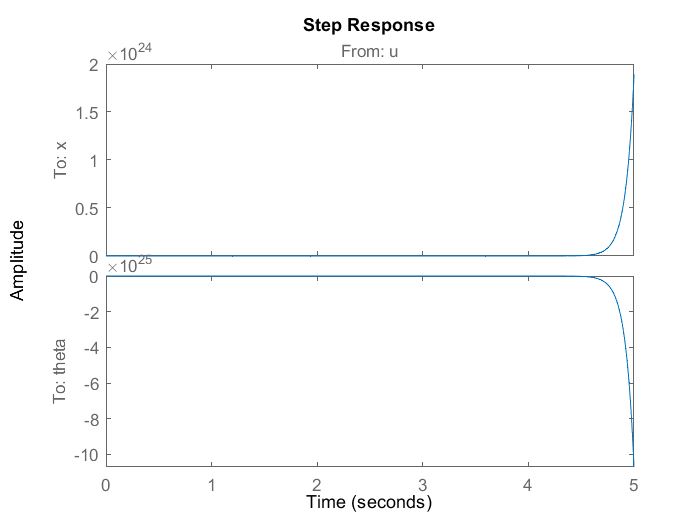

figure; step(olsys_tf) % notice the instability of the system

## Stabilizing the System with SS Feedback P control

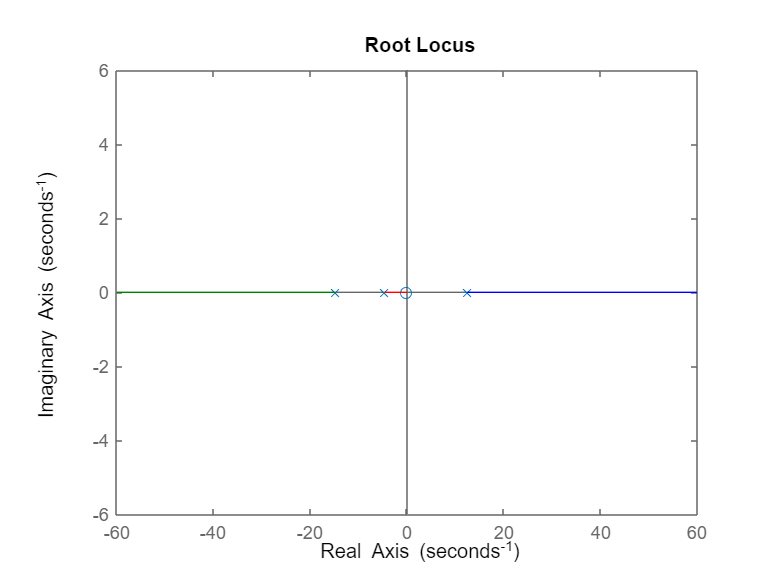

figure;
rlocus(olsys_tf(2)) % root locus of theta/u

% from the root locus plot theta/u, we see that there will always be a pole
% in the RHP, so we have to do a state-space feedback to stabilize the system

% seeing if the system is controllable and observable (full rank = yes)
rank(ctrb(A,B))

ans = 4

rank(obsv(A,C))

ans = 4

% arbitrary location of stable poles 2022/09/28
% TO DO - design response of system to find desired pole locations
p = [-3, -4, -5, -6];
K = acker(A,B,p)

K =    -0.7024   -2.3235   -5.6447   -0.3983


% u = -Kx + r => xdot = (A - B*K)*x + B*r
Abar = A-B*K;
% Closed Loop system
clsys = ss(Abar,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

clsys =
 
  A = 
                      x      x_dot      theta  theta_dot
   x                  0          1          0          0
   x_dot          2.977      2.828      19.69      1.688
   theta              0          0          0          1
   theta_dot     -36.73      -34.9       -122     -20.83
 
  B = 
                  u
   x              0
   x_dot      4.238
   theta          0
   theta_dot  -52.3
 
  C = 
                  x      x_dot      theta  theta_dot
   x              1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



clsys_tf = tf(clsys)

clsys_tf =
 
  From input "u" to output...
                4.238 s^2 - 512.5
   x:  ------------------------------------
       s^4 + 18 s^3 + 119 s^2 + 342 s + 360
 
            -52.3 s^2 - 6.63e-14 s + 2.744e-14
   theta:  ------------------------------------
           s^4 + 18 s^3 + 119 s^2 + 342 s + 360
 
Continuous-time transfer function.



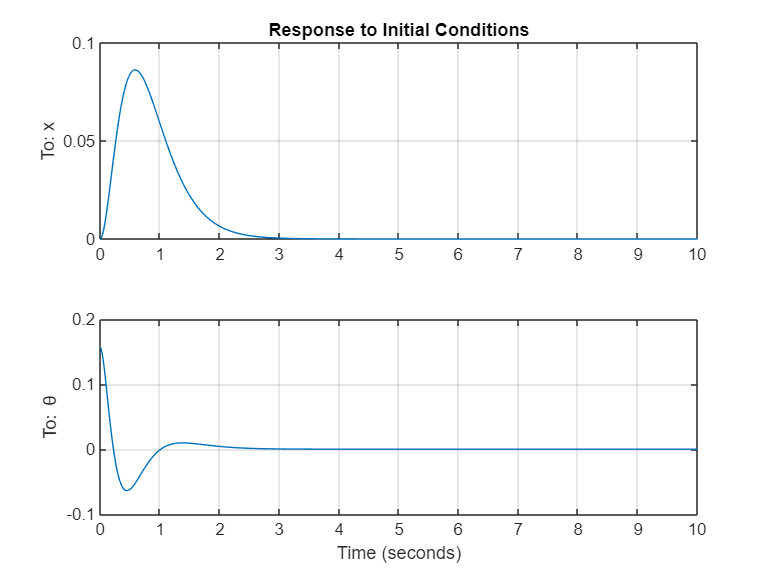

[y_init,t_init,beta_state_init] = initial(clsys,[0;0;pi/20;0],10);
figure;
tiledlayout(2,1);
nexttile;
plot(t_init, y_init(:,1)); title('Response to Initial Conditions'); ylabel('To: x');
grid on
nexttile;
plot(t_init,y_init(:,2)); ylabel('To: \theta'); xlabel('Time (seconds)')
grid on

### Animation Parameters

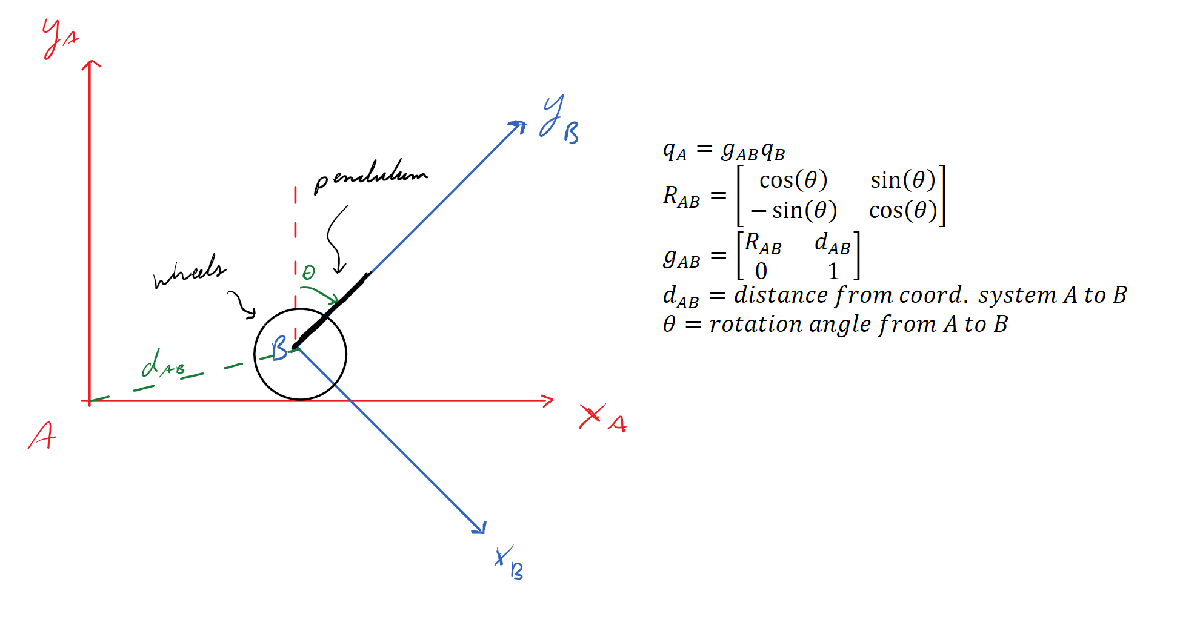

th_wheel = linspace(0,2*pi,100);
wheel = [r_real*cos(th_wheel); r_real*sin(th_wheel) + r_real]; % the vertex locations of the "cart" (wheels)

th = linspace(0,2*pi) ; % the points for generating the plot of a circle for Center of Mass
r_CoM = 0.005; % radius of circle 2 (CoM)..?
cB = [0; l_real]; % location of the pole CoM, B-frame
eB = [0; x_bump]; % location of the END of the pole (approx. bumper CoM), B-frame 


### Animating the system response to initial parameters

x = beta_state_init(:,1);
theta = beta_state_init(:,3);
figure;
cart = plot(x(1) + wheel(1,:),wheel(2,:),'r');
hold on

R_AB = [cos(theta(1)) sin(theta(1)); -sin(theta(1)) cos(theta(1))]; % rotational matrix
d_AB = [x(1); r_real]; % location of center of B-frame w.r.t. A-frame
g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
cA = g_AB*[cB; 1]; cA = cA(1:2); % pole CoM, A-frame
eA = g_AB*[eB; 1]; eA = eA(1:2); % pole end, A-frame

CoMx = cA(1) + r_CoM*cos(th) ; % Center of Mass of pole, x
CoMy = cA(2) + r_CoM*sin(th) ; % Center of Mass of pole, y

minx = min(x) - r_real; maxx = max(x) + r_real;

CoM = plot(CoMx,CoMy,'bl') ;
bar = plot([d_AB(1) eA(1)], [d_AB(2) eA(2)],'b');

fprintf("initial x value: %.5d m \ninitial theta valuue: %.5f rad",x(1),theta(1))

initial x value: 00000 m 
initial theta valuue: 0.15708 rad

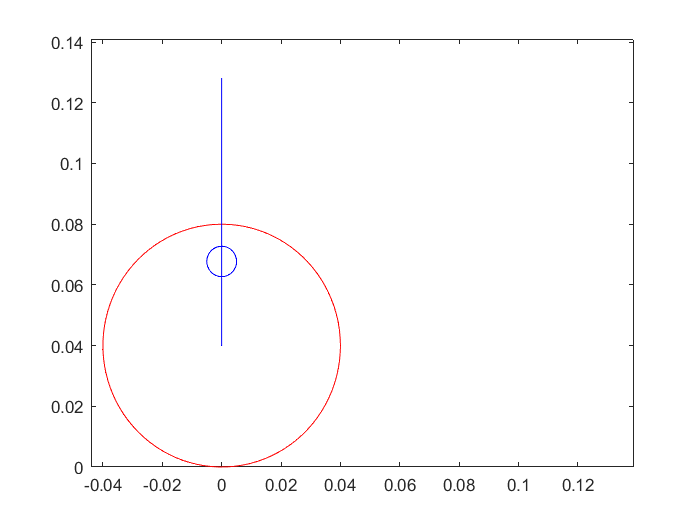

timestep = gradient(t_init);
%% animation
% only need half of the time steps for stability, plotting every 5th step
for i = 2:5:round(length(x)*0.5)
    wheel_draw = wheel + [repmat(x(i),[1,size(wheel,2)]); zeros(1,size(wheel,2))];
    
    R_AB = [cos(theta(i)) sin(theta(i)); -sin(theta(i)) cos(theta(i))]; % rotational matrix
    d_AB = [x(i); r_real]; % location of center of B-frame w.r.t. A-frame
    g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
    cA = g_AB*[cB; 1]; cA = cA(1:2);
    eA = g_AB*[eB; 1]; eA = eA(1:2);
    
    CoMx = cA(1) + r_CoM*cos(th); 
    CoMy = cA(2) + r_CoM*sin(th);
    bar_x = [d_AB(1) eA(1)];
    bar_y = [d_AB(2) eA(2)];

    set(cart,'XData',wheel_draw(1,:),'YData',wheel_draw(2,:)) ;
    set(CoM,'XData',CoMx,'YData',CoMy) ;
    set(bar,'XData',bar_x,'YData',bar_y) ;
    axis([minx maxx 0 (eB(2) + r_real)]*1.1)     
    drawnow
    pause(timestep(i)/4) % heuristically, calculations take non-negligible amount of time
end

## Desired output tracking with SS Feedback P control

yd = [1; 0]; % x position: 1m, phi: 0rad deviation
clsys_gain = -C/Abar*B % this is the gain of the system with a step input

clsys_gain =    -1.4237
         0


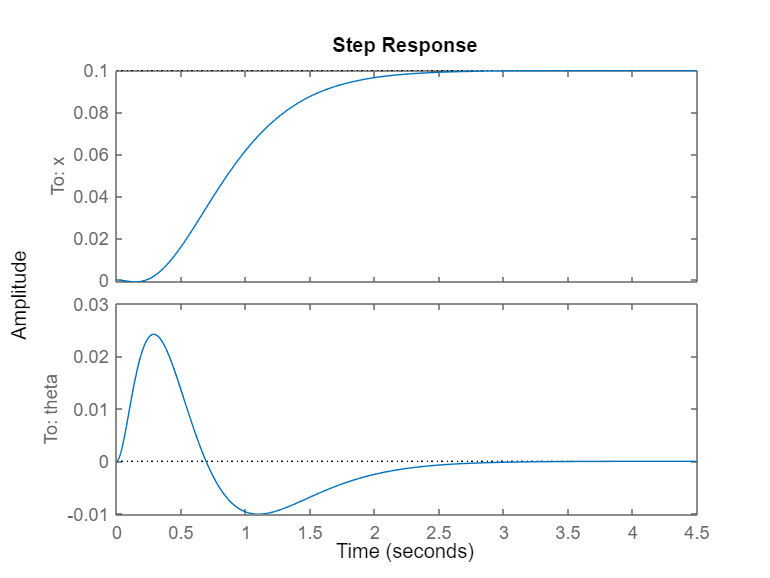

% from clsys_gain, we can see that phi will always return to 0, so we can
% only control the output x:
clsys_ref = yd(1)/clsys_gain(1)/10; % [m] reference input

figure;
% step response with defined input so that output is at desired location
[y_track,t_track,beta_state_track] = step(clsys*clsys_ref);
step(clsys*clsys_ref)

### Animating the system response to a desired output

x = beta_state_track(:,1);
theta = beta_state_track(:,3);
figure;
cart = plot(x(1) + wheel(1,:),wheel(2,:),'r');
hold on

R_AB = [cos(theta(1)) sin(theta(1)); -sin(theta(1)) cos(theta(1))]; % rotational matrix
d_AB = [x(1); r_real]; % location of center of B-frame w.r.t. A-frame
g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
cA = g_AB*[cB; 1]; cA = cA(1:2); % pole CoM, A-frame
eA = g_AB*[eB; 1]; eA = eA(1:2); % pole end, A-frame

CoMx = cA(1) + r_CoM*cos(th) ; % Center of Mass of pole, x
CoMy = cA(2) + r_CoM*sin(th) ; % Center of Mass of pole, y

minx = min(x) - r_real; maxx = max(x) + r_real;

CoM = plot(CoMx,CoMy,'bl') ;
bar = plot([d_AB(1) eA(1)], [d_AB(2) eA(2)],'b');

fprintf("initial x value: %.5d m \ninitial theta valuue: %.5f rad",x(1),theta(1))

initial x value: 00000 m 
initial theta valuue: 0.00000 rad

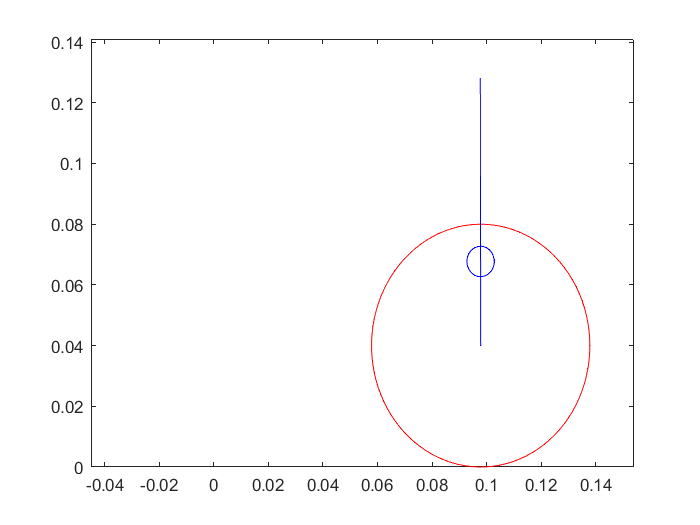

timestep = gradient(t_track);
%% animation
% only need half of the time steps for stability, plotting every 5th step
for i = 2:5:round(length(x)*0.5)
    wheel_draw = wheel + [repmat(x(i),[1,size(wheel,2)]); zeros(1,size(wheel,2))];
    
    R_AB = [cos(theta(i)) sin(theta(i)); -sin(theta(i)) cos(theta(i))]; % rotational matrix
    d_AB = [x(i); r_real]; % location of center of B-frame w.r.t. A-frame
    g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
    cA = g_AB*[cB; 1]; cA = cA(1:2);
    eA = g_AB*[eB; 1]; eA = eA(1:2);
    
    CoMx = cA(1) + r_CoM*cos(th); 
    CoMy = cA(2) + r_CoM*sin(th);
    bar_x = [d_AB(1) eA(1)];
    bar_y = [d_AB(2) eA(2)];

    set(cart,'XData',wheel_draw(1,:),'YData',wheel_draw(2,:)) ;
    set(CoM,'XData',CoMx,'YData',CoMy) ;
    set(bar,'XData',bar_x,'YData',bar_y) ;
    axis([minx maxx 0 (eB(2) + r_real)]*1.1)     
    drawnow
    pause(timestep(i)/2) % heuristically, calculations take non-negligible amount of time
end

## Stabilize the System with SS Feedback PI control

With integral control, we have to define u as follows, introducing an additional state to the system since we are increasing the order of the transfer function:

$\dot{x} = A x + B u$  , $y = Cx$


$$u = -K_p x - K_i x_i$$



$$x_i = \int_{0}^{t} e\  d\tau \ \,\ where\ e = -y_d + x$$


yd is the desired output of the x position of the cart.

NOTE: not using integral control on the angle of the pendulum since it led to unstable control. Likely the two integrating errors were fighting each other causing an undesireable control scenario (to be looked into in the future).

Thus we have:


$$\pmatrix{\dot{x} \cr \dot{x_i}} = \pmatrix{ (A - BK_p) & -BK_i \cr \matrix{1 & 0 & 0 & 0} & 0} \pmatrix{x \cr x_i} + \pmatrix{0 \cr -y_d}$$


In another representation (more intuitive for using the Bass-Gura solution for placing the poles via the acker() or place() command):


$$\pmatrix{\dot{x} \cr \dot{x_i}} = \pmatrix{A & 0 \cr C(1,:) & 0} \pmatrix{x \cr x_i} - \pmatrix{B \cr 0} \pmatrix{K_p & K_i} \pmatrix{x \cr x_i} + \pmatrix{0 \cr -y_d}$$



$$\Rightarrow \pmatrix{\dot{x} \cr \dot{x_i}} = \bar{A} \pmatrix{x \cr x_i} - \bar{B} K \pmatrix{x \cr x_i} + \pmatrix{0 \cr -y_d}$$


$\Rightarrow \pmatrix{\dot{x} \cr \dot{x_i} } = \hat{A} \pmatrix{x \cr x_i} + \pmatrix{0 \cr -y_d}$, where $\hat{A} = \bar{A} - \bar{B}K$

Abar = [A zeros(4,1); C(1,:) zeros(1,1)];
Bbar = [B; zeros(1,1)];
Cbar = [C zeros(2,1)];

% Location of Poles logic: 2022/10/24
% complex poles chosen along the 45deg angle so that the damping is optimal
% Real pole relative to the complex poles chosen so that the speed of the
% real pole dominates the system response.
p = [-3, -14.1*(1 + 1i*[1, -1]), -10.6*(1 + 1i*[1, -1])];
K = acker(Abar,Bbar,p)

K =  -260.7746  -41.9353  -50.6116   -4.2663 -523.0189


yd = 0.1; % [m; rad] integrating error for x only

% Closed Loop system
Ahat = Abar-Bbar*K;
Bhat = [zeros(4,1); -yd];
Chat = [C zeros(2,1)];
Dhat = zeros(2,1);
states = {'x' 'x_dot' 'theta' 'theta_dot' 'x_i'};
inputs = {'u'};
outputs = {'x'; 'theta'};
clsys_int = ss(Ahat,Bhat,Chat,Dhat,'statename',states,'inputname',inputs,'outputname',outputs)

clsys_int =
 
  A = 
                       x       x_dot       theta   theta_dot         x_i
   x                   0           1           0           0           0
   x_dot            1105       170.7       210.3       18.08        2217
   theta               0           0           0           1           0
   theta_dot  -1.364e+04       -2107       -2474      -223.1  -2.735e+04
   x_i                 1           0           0           0           0
 
  B = 
                 u
   x             0
   x_dot         0
   theta         0
   theta_dot     0
   x_i        -0.1
 
  C = 
                  x      x_dot      theta  theta_dot        x_i
   x              1          0          0          0          0
   theta          0          0          1          0          0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



clsys_int_tf = tf(clsys_int)

clsys_int_tf =
 
  From input "u" to output...
                     -221.7 s^2 + 3.938e-13 s + 2.681e04
   x:  ----------------------------------------------------------------
       s^5 + 52.4 s^4 + 1368 s^3 + 1.843e04 s^2 + 1.337e05 s + 2.681e05
 
                          2735 s^2 + 1.853e-10 s + 7.421e-10
   theta:  ----------------------------------------------------------------
           s^5 + 52.4 s^4 + 1368 s^3 + 1.843e04 s^2 + 1.337e05 s + 2.681e05
 
Continuous-time transfer function.



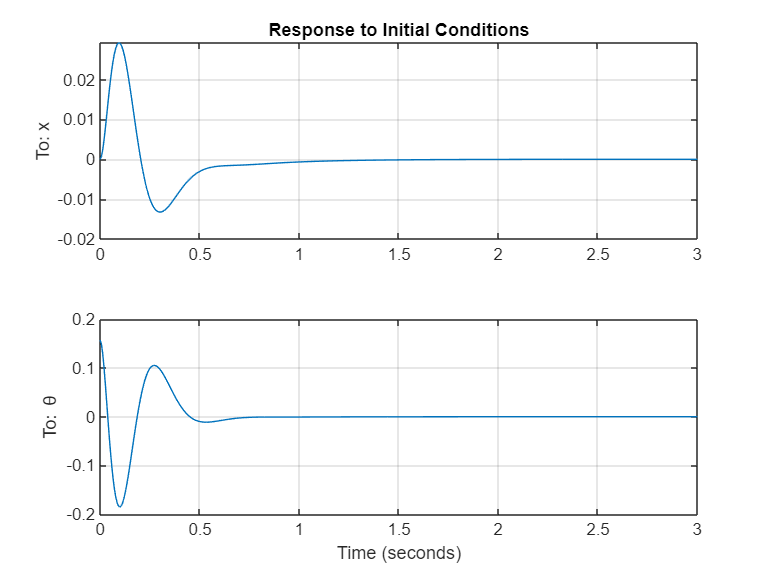

[y_int_init,t_int_init,beta_state_int_init] = initial(clsys_int,[0; 0 ; pi/20; 0; 0],3);
figure;
tiledlayout(2,1);
nexttile;
plot(t_int_init, y_int_init(:,1)); title('Response to Initial Conditions'); ylabel('To: x');
grid on
nexttile;
plot(t_int_init,y_int_init(:,2)); ylabel('To: \theta'); xlabel('Time (seconds)')
grid on

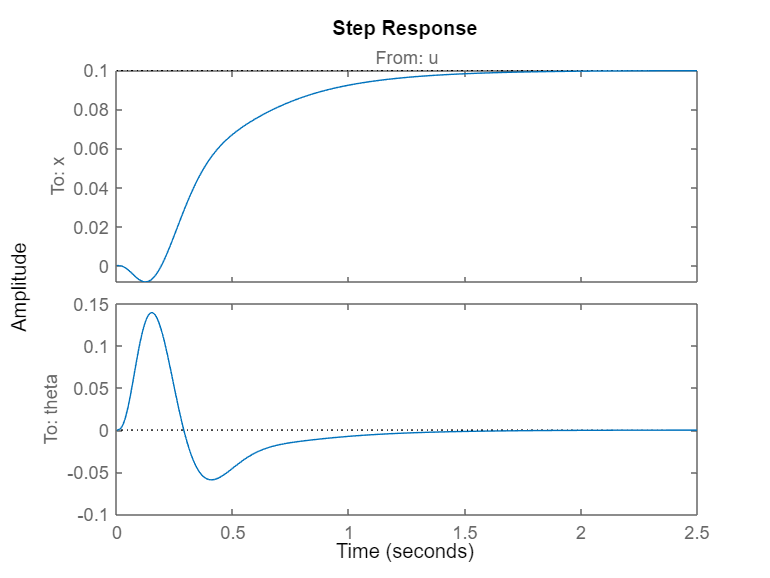


% Step Response of Integrator
figure;
[y_int_track,t_int_track,beta_state_int_track] = step(clsys_int);
step(clsys_int)

### Animating the system response to a desired output

x = beta_state_int_track(:,1);
theta = beta_state_int_track(:,3);
figure;
cart = plot(x(1) + wheel(1,:),wheel(2,:),'r');
hold on

R_AB = [cos(theta(1)) sin(theta(1)); -sin(theta(1)) cos(theta(1))]; % rotational matrix
d_AB = [x(1); r_real]; % location of center of B-frame w.r.t. A-frame
g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
cA = g_AB*[cB; 1]; cA = cA(1:2); % pole CoM, A-frame
eA = g_AB*[eB; 1]; eA = eA(1:2); % pole end, A-frame

CoMx = cA(1) + r_CoM*cos(th) ; % Center of Mass of pole, x
CoMy = cA(2) + r_CoM*sin(th) ; % Center of Mass of pole, y

minx = min(x) - r_real; maxx = max(x) + r_real;

CoM = plot(CoMx,CoMy,'bl') ;
bar = plot([d_AB(1) eA(1)], [d_AB(2) eA(2)],'b');

fprintf("initial x value: %.5d m \ninitial theta valuue: %.5f rad",x(1),theta(1))

initial x value: 00000 m 
initial theta valuue: 0.00000 rad

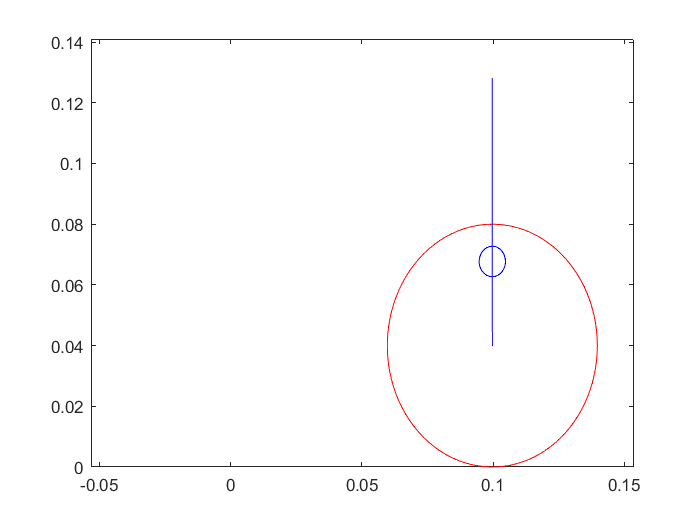

timestep = gradient(t_int_track);
%% animation
% plotting every 5th step
for i = 2:5:round(length(x))
    wheel_draw = wheel + [repmat(x(i),[1,size(wheel,2)]); zeros(1,size(wheel,2))];
    
    R_AB = [cos(theta(i)) sin(theta(i)); -sin(theta(i)) cos(theta(i))]; % rotational matrix
    d_AB = [x(i); r_real]; % location of center of B-frame w.r.t. A-frame
    g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
    cA = g_AB*[cB; 1]; cA = cA(1:2);
    eA = g_AB*[eB; 1]; eA = eA(1:2);
    
    CoMx = cA(1) + r_CoM*cos(th); 
    CoMy = cA(2) + r_CoM*sin(th);
    bar_x = [d_AB(1) eA(1)];
    bar_y = [d_AB(2) eA(2)];

    set(cart,'XData',wheel_draw(1,:),'YData',wheel_draw(2,:)) ;
    set(CoM,'XData',CoMx,'YData',CoMy) ;
    set(bar,'XData',bar_x,'YData',bar_y) ;
    axis([minx maxx 0 (eB(2) + r_real)]*1.1)     
    drawnow
    pause(timestep(i)/2) % heuristically, calculations take non-negligible amount of time
end

NEXT STEPS:

- Substitute in real values (estimated) - DONE

- get the integral control working, - DONE

- Optimal control

- discretize the control solutions (state space, integral, optimal)

- Start coding into arduino and test; tune values as needed

- (? then do an optimal control solution ?)